%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Course :	Multimedia Data Security (2016)
% Project: 	Spread Spectrum
%           Watermark Embedding
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
close all; clear all;

## Read original image

I    = imread('lena.tif','tif');
[dimx,dimy] = size(I);
Id   = double(I);

## Generate random watermark

rng(6);
nValues=1000;
div=10;
groupSize=4;
w = round(rand(1,1000));
save('watermark','w');

## Define watermark strenght

alpha = 0.9;

## DCT transform

It = dct2(Id);
It_re = reshape(It,1,dimx*dimy);

## Modulo and sign

It_sgn = sign(It_re);
It_mod = abs(It_re);

## Modulo sorting

[It_sort,Ix] = sort(It_mod,'descend');

## Embedding

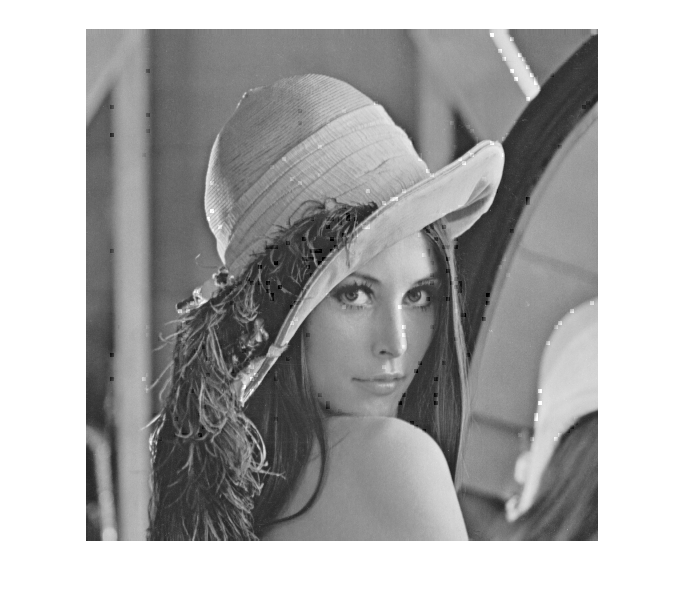

Itw_mod = It_mod; 
ent=zeros((512/groupSize),(512/groupSize));
newIma=I;
for j=1:(512/groupSize)
    for k=1:(512/groupSize)
        tmpMat=I((groupSize*(j-1)+1):(j*groupSize),(groupSize*(k-1)+1):(k*groupSize));
        ent(j,k)=entropy(tmpMat);
    end
end
count=1;
res= sort(reshape(ent,1,(512/groupSize)*(512/groupSize)),'descend');
tresh=res(1000);
for j=1:(512/groupSize)
    for k=1:(512/groupSize)
        if(ent(j,k)>=tresh)
            posi(count,:)=[j k];
            count=count+1;
            newIma((groupSize*(j-1)+1):(j*groupSize),(groupSize*(k-1)+1):(k*groupSize))=zeros(groupSize);
        end
    end
end

k = 2;
for j = 1:nValues
    m = Ix(k);
    %Itw_mod(m) = It_mod(m)*(1+alpha);
    Itw_mod(m) = It_mod(m)*(1+alpha*w(j));
%     Itw_mod(m) = It_mod(m)*exp(alpha*w(j));
    k = k+1;
 % k=round(k+(div/k));
end

% recover sign
It_new = Itw_mod.*It_sgn;

%watermark, from vector to matrix
It_newi=reshape(It_new,dimx,dimy);
%inverse dct
I_inv = idct2(It_newi);
III=I;
[ny,nx]=size(posi);
if(ny>size(w))    
    for co=1:ny
        newX=groupSize*(posi(co, 2)-1)+1;
        newY=groupSize*(posi(co, 1)-1)+1;
        if(co<1001)
            if(w(co)==1)
            
                III(newY:newY+groupSize-1,newX:newX+groupSize-1)=I_inv(newY:newY+groupSize-1,newX:newX+groupSize-1);
            end
         end
    end
end
imshow(III,[]);

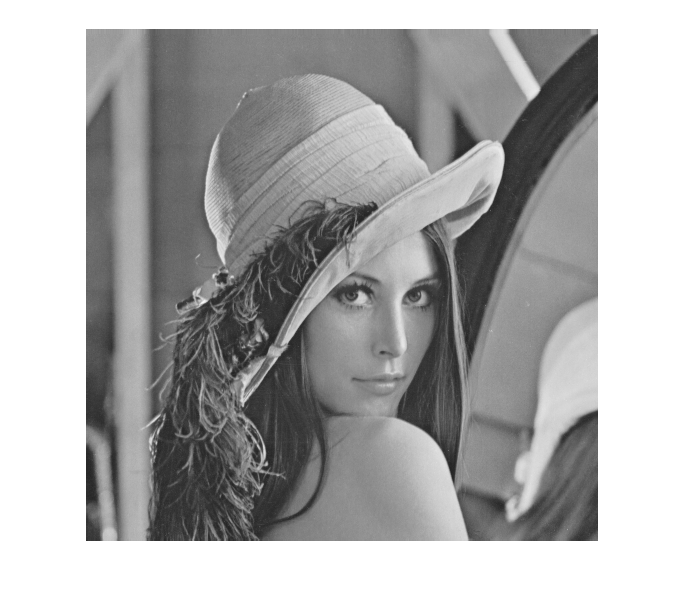

figure(); imshow(I);

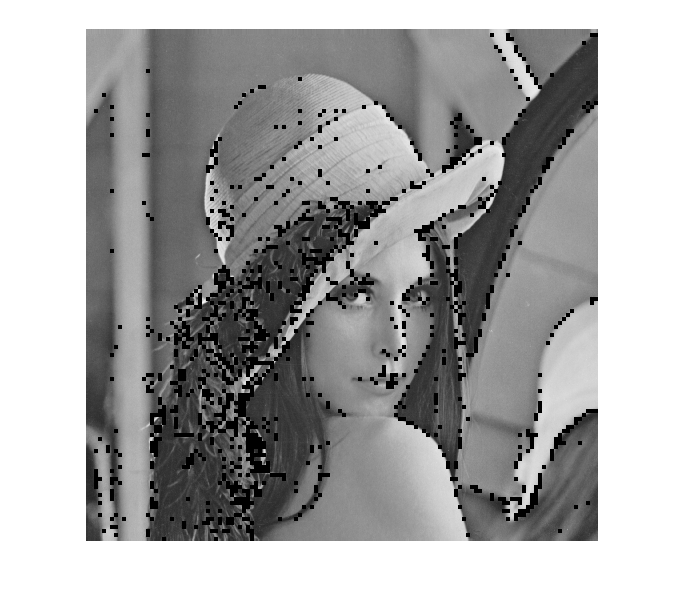

figure(); imshow(newIma);

 
%save watermarked image
imwrite(uint8(I_inv),'SSwat.tif','tif'); 
 
PSNR(uint8(I_inv),uint8(Id)) 

PSNR = +19.33 dB



WPSNR(uint8(III),uint8(Id))

WPSNR = +41.80 dB




WPSNR(uint8(I_inv),uint8(Id))

WPSNR = +25.28 dB



max(max(ent))

ans = 4

min(min(ent))

ans = 0.9544

mean(mean(ent))

ans = 3.0894